clc; clear; close all
% addpath 'F:\code\functions'
% afdata1 = importdata("af_data1.txt");
% afdata2 = importdata("af_data2.txt");
% afdata3 = importdata("af_data3.txt");
% scandata1 = importdata("wire1scan1.txt");
% scandata2 = importdata("wire1scan2.txt");
% scandata3 = importdata("wire1scan3.txt");
% af1 = sortdata(separate_wire_data(afdata1,1));
% af2 = sortdata(separate_wire_data(afdata2,1));
% af3 = sortdata(separate_wire_data(afdata3,1));

% clearvars -except data origin sorted originaldata
% data = table2array(sorted);
wire_1 = importdata("wire1sorted.txt");
wire_2 = importdata("wire2sorted.txt");
wire_3 = importdata("wire3sorted.txt");
wire_4 = importdata("wire4sorted.txt");
% AFdata = table2array(duringAF);
%origin = table2array(originaldata);
% wire_num = data(:,1);
%original_order = origin(:,1);
lens = 40; %20 40
if lens == 10
    pixeltoum = 0.65; %um/pixal
elseif lens == 40
    pixeltoum = 0.1625; %um/pixal
end

sharpness_1 = wire_1(:,2);
x_1 = wire_1(:,4)*pixeltoum;
y_1 = wire_1(:,5)*pixeltoum;
z_1 = wire_1(:,3);
wire1_width = wire_1(1,9)*pixeltoum;
wire1_length = wire_1(:,6)*pixeltoum;
smoothdata_wire1_length = smoothdata(wire1_length);
wire1_ref_length = wire1_length(1);

sharpness_2 = wire_2(:,2);
x_2 = wire_2(:,4)*pixeltoum;
y_2 = wire_2(:,5)*pixeltoum;
z_2 = wire_2(:,3);
wire2_width = wire_2(1,9)*pixeltoum;
wire2_length = wire_2(:,6)*pixeltoum;
smoothdata_wire2_length = smoothdata(wire2_length);
wire2_ref_length = wire2_length(1);

sharpness_3 = wire_3(:,2);
x_3 = wire_3(:,4)*pixeltoum;
y_3 = wire_3(:,5)*pixeltoum;
z_3 = wire_3(:,3);
wire3_width = wire_3(1,9)*pixeltoum;
wire3_length = wire_3(:,6)*pixeltoum;
smoothdata_wire3_length = smoothdata(wire3_length);
wire3_ref_length = wire3_length(1);

wire4_width = wire_4(1,9)*pixeltoum;
wire4_length = wire_4(:,6)*pixeltoum;
wire4_ref_length = wire4_length(1);
smoothdata_wire4_length = smoothdata(wire4_length);

total_time = 0;
for i = 1:length(wire1_length)
    if wire1_ref_length < wire1_length(i)
        wire1_ref_length = wire1_length(i);
    end
    wire1_angle(i) = real(acosd((wire1_length(i)-abs(wire1_width*(wire1_length(i)/wire1_ref_length)))...
        /(wire1_ref_length-abs(wire1_width*(wire1_length(i)/wire1_ref_length)))));
    wire1_mod(i) =  (real(acosd((smoothdata_wire1_length(i)-wire1_width)/(wire1_ref_length-wire1_width))));
    wire1_raw(i) =  (real(acosd((wire1_length(i)-wire1_width)/(wire1_ref_length-wire1_width))));
    if wire1_length(i) <= wire1_width
        wire1_raw(i) = 90;
    end
end
for i = 1:length(wire2_length)
    if wire2_ref_length < wire2_length(i)
        wire2_ref_length = wire2_length(i);
    end
    wire2_mod(i) = (real(acosd((smoothdata_wire2_length(i)-wire2_width)/(wire2_ref_length-wire2_width))));
    wire2_raw(i) = ((real(acosd((wire2_length(i)-wire2_width)/(wire2_ref_length-wire2_width)))));
    wire2_angle(i) = real(acosd((wire2_length(i)-abs(wire2_width*(wire2_length(i)/wire2_ref_length)))...
        /(wire2_ref_length-abs(wire2_width*(wire2_length(i)/wire2_ref_length)))));
    
    if wire2_length(i) <= wire2_width
        wire2_raw(i) = 90;
    end
end
for i = 1:length(wire3_length)
    if wire3_ref_length < wire3_length(i)
        wire3_ref_length = wire3_length(i);
    end
    wire3_mod(i) = (real(acosd((smoothdata_wire3_length(i)-wire3_width)/(wire3_ref_length-wire3_width))));
    wire3_raw(i) = (real(acosd((wire3_length(i)-wire3_width)/(wire3_ref_length-wire3_width))));
    wire3_angle(i) = real(acosd((wire3_length(i)-abs(wire3_width*(wire3_length(i)/wire3_ref_length)))...
        /(wire3_ref_length-abs(wire3_width*(wire3_length(i)/wire3_ref_length)))));
    if wire3_length(i) <= wire3_width
        wire3_raw(i) = 90;
    end
end
for i = 1:length(wire4_length)
    if wire4_ref_length < wire4_length(i)
        wire4_ref_length = wire4_length(i);
    end
    
    wire4_angle(i) = real(acosd((wire4_length(i)-abs(wire4_width*(wire4_length(i)/wire4_ref_length)))...
        /(wire4_ref_length-abs(wire4_width*(wire4_length(i)/wire4_ref_length)))));
    wire4_mod(i) = (real(acosd((smoothdata_wire4_length(i)-wire4_width)/(wire4_ref_length-wire4_width))));
    wire4_raw(i) = (real(acosd((wire4_length(i)-wire4_width)/(wire4_ref_length-wire4_width))));
    if wire4_length(i) <= wire4_width
        wire4_raw(i) = 90;
    end
end

x_axis = zeros(1,length(wire_1)+length(wire_2)+length(wire_3)+length(wire_4));
total_time = 0;
for i = 1:length(wire_1)
    x_axis(4*i-3) = wire_1(i,8);
end
for i = 1:length(wire_2)
    x_axis(4*i-2) = wire_2(i,8);
end
for i = 1:length(wire_3)
    x_axis(4*i-1) = wire_3(i,8);
end
for i = 1:length(wire_4)
    x_axis(4*i) = wire_4(i,8);
end
for i = 1:length(x_axis)
    real_time = x_axis(i);
    total_time = real_time + total_time;
    timeline(i) = total_time;
end
timeline = transpose(timeline);

for i = 1:length(wire_1)
    wire1_time(i) = timeline(4*i-3);
end
for i = 1:length(wire_2)
    wire2_time(i) = timeline(4*i-2);
end
for i = 1:length(wire_3)
    wire3_time(i) = timeline(4*i-1);
end
for i = 1:length(wire_4)
    wire4_time(i) = timeline(4*i);
end

% for i = 1:length(data)
%     real_time = data(i,8);
%     total_time = real_time + total_time;
%     x_axis(i) = total_time;
% end
% x_axis = transpose(x_axis);
% % real_time = transpose(real_time);
% wire1_angle = transpose(wire1_angle);
% % figure(1)
% % plot(wire1_angle)
% % xlabel('AF cycles')
% % ylabel('degrees')

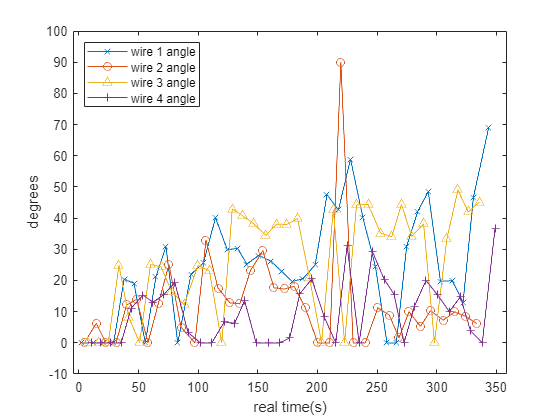

figure(1)
plot(wire1_time, wire1_raw,'-x'); hold on
plot(wire2_time, wire2_raw,'-o'); hold on
plot(wire3_time, wire3_raw,'-^'); hold on
plot(wire4_time, wire4_raw,'-+'); hold off
xlabel('real time(s)');
xlim([-5 round(timeline(end))+10]);
ylabel('degrees');
ylim([-10 100]);
legend('wire 1 angle','wire 2 angle','wire 3 angle','wire 4 angle','Location','northwest')

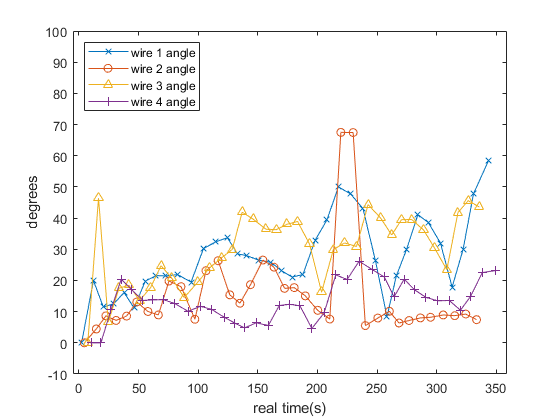

figure(2)
plot(wire1_time, wire1_mod,'-x'); hold on
plot(wire2_time, wire2_mod,'-o'); hold on
plot(wire3_time, wire3_mod,'-^'); hold on
plot(wire4_time, wire4_mod,'-+'); hold off
xlabel('real time(s)');
xlim([-5 round(timeline(end))+10]);
ylabel('degrees');
ylim([-10 100]);
legend('wire 1 angle','wire 2 angle','wire 3 angle','wire 4 angle','Location','northwest')